# **Exercise session 2B - Solutions**

## ** Duffing oscillator**

The dynamics of the Duffing oscillator can be described by the nonlinear state-space equations


$$\begin{array}{l}
{\dot{\;x} }_1 =x_2 \\
{\dot{\;x} }_2 =\frac{g}{l}\sin \;x_1 -\frac{\alpha }{{\textrm{ml}}^2 }x_1 -\frac{k}{{\textrm{ml}}^2 }x_2 +u
\end{array}$$


where the values of the physical parameters are given by:

l = 1;      % Length of the mass-less flexible arm
alpha = 16; % Coefficient for restoring torque: controls the linear stiffness
m = 2;      % Mass of the metal ball attached to the arm
k = 4;      % Coefficient for damping torque: controls the amount of damping
g = 9.81;   % Gravitational acceleration

A Simulink model of the Duffing oscillator based on these nonlinear equations can be found in the `duffingNL.slx` file. Note that the Interpreted MATLAB function block executes the commands specified in the `duffing_func.m` file. The initial condition of the system can be modified through the variable `x_init`.

#### Equilibrium points

We calculate the equilibrium points when $\bar{u} =0$ by setting ${\dot{\;x} }_1 =0$ and ${\dot{\;x} }_2 =0$.

Then, we have $x_2 =0$ and $\frac{g}{l}\sin \;x_1 =\frac{\alpha }{{\textrm{ml}}^2 }x_1$.

The last equation may have one or three roots depending on the parameters. In our case, the system has three roots as shown in the following plot.

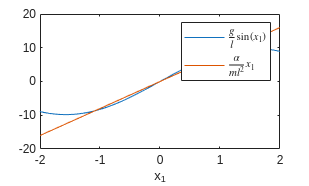

x1 = linspace(-2,2,51);
plot(x1, g/l*sin(x1), x1, alpha/(m*l^2)*x1)
xlabel("x_1")
legend('$$\frac{g}{l}\sin(x_1)$$', '$$\frac{\alpha}{ml^2}x_1$$', 'Interpreter','latex')

Then, we can find the roots using the `vpasolve` function:

syms x1
x_root = vpasolve(g/l*sin(x1) - alpha/(m*l^2)*x1, 1)

$$x\_root = 1.0835399554748190936267218086804$$

x_root = double(x_root);

Note that we passed a starting value to obtain the root closest to the value $1$.

As linear functions and $\sin \left(\cdot \;\right)$ are odd functions, the roots have rotational symmetry. Thus, the equilibrium points are:

xbar_0 = [0,0]

xbar_0 =      0     0


xbar_1 = [x_root,0]

xbar_1 =     1.0835         0


xbar_2 = [-x_root,0]

xbar_2 =    -1.0835         0


#### Linearization

To linearize the system, we follow the steps indicated in the statement of the exercise, see also the `duffingNL.slx` file. The following lines of code compute the linearized system dynamics around the three equilibrium points of the system.

linsys(1).xbar = xbar_0;
linsys(2).xbar = xbar_1;
linsys(3).xbar = xbar_2;
for i=1:3
    x_init = linsys(i).xbar;
    sim('duffingNL');
    linsys(i).A = duffingNL_Timed_Based_Linearization.a;
    linsys(i).B = duffingNL_Timed_Based_Linearization.b;
    linsys(i).C = duffingNL_Timed_Based_Linearization.c;
    linsys(i).D = duffingNL_Timed_Based_Linearization.d;
end

Compare the linearized models obtained numerically with the ones you computed in point 2!

### Simulation of the non-linear and linearized models for different initial conditions

In the file `duffing.slx`, we have built the three linearized models together with the original nonlinear model. We now simulate them with different initial conditions by running the code below.

To compute the initial condition of the different linearized systems, recall that:


$$\delta x_i \left(0\right)=x_i \left(0\right)-\bar{x_i }$$


Similarly, to properly compare the state trajectory of each linearized system with the one of the original nonlinear system, recall that:


$$x_i \left(t\right)=\delta x_i \left(t\right)+\bar{x_i }$$


simu(1).x0 = [0,0];
simu(2).x0 = [0.5,0];
simu(3).x0 = [-0.5,0];
for i=1:3 % For each initial condition...
    x_init_NL = simu(i).x0;
    for j=1:3
        linsys(j).x_init = simu(i).x0 - linsys(j).xbar;
    end
    out = sim('duffing');
    simu(i).tout = out.tout;
    simu(i).xNL = out.simoutNL;
    simu(i).xLin1 = out.simoutLin1 + linsys(1).xbar;
    simu(i).xLin2 = out.simoutLin2 + linsys(2).xbar;
    simu(i).xLin3 = out.simoutLin3 + linsys(3).xbar;
end

Finally, we plot the simulation results.

1) State-space trajectories starting at (0.0, 0.0):

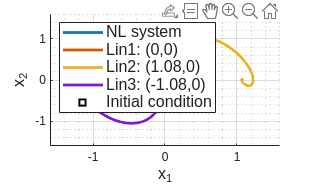

2) State-space trajectories starting at (0.5, 0.0):

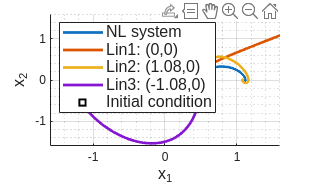

3) State-space trajectories starting at (-0.5, 0.0):

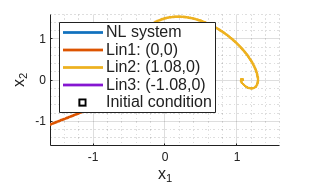

for i=1:3
    fprintf("%i) State-space trajectories starting at (%.1f, %.1f):", ...
        i, simu(i).x0(1), simu(i).x0(2))
    figure; hold on
    plot(simu(i).xNL(:,1), simu(i).xNL(:,2), 'LineWidth',2)
    plot(simu(i).xLin1(:,1), simu(i).xLin1(:,2), 'LineWidth',2)
    plot(simu(i).xLin2(:,1), simu(i).xLin2(:,2), 'LineWidth',2)
    plot(simu(i).xLin3(:,1), simu(i).xLin3(:,2), 'LineWidth',2)
    scatter(simu(i).x0(1), simu(i).x0(2), 'Marker','square', 'MarkerEdgeColor','k', 'LineWidth',2)
    grid on; grid minor;
    hold off
    xlim([-1.6 1.6])
    ylim([-1.6 1.6])
    xlabel('x_1', "FontSize", 12)
    ylabel('x_2', "FontSize", 12)
    legend('NL system', 'Lin1: (0,0)', 'Lin2: (1.08,0)', 'Lin3: (-1.08,0)', ...
        'Initial condition', 'FontSize', 12, 'Location', 'northwest')
end